%{
ES115 Smartphone Sensor Data Exploration
 originally from Final module Project Bank - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-25


State the problem (Purpose):
 Electric bill costs are compared based on usage values to determine which bill would be most cost effective.

Describe input values (Knowns)and required output (Unknowns) 
    Input: - Linear and Piecewise function
          - usage range
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}

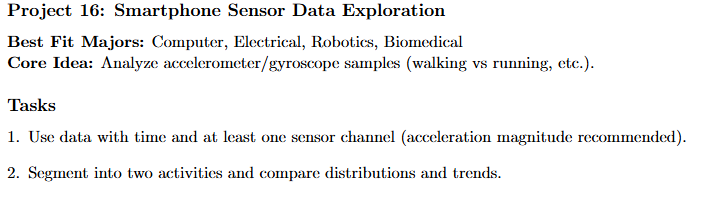

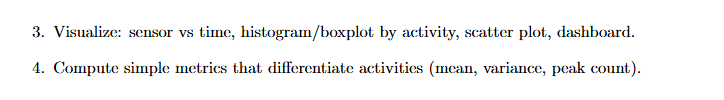


clear; clc; close all;  % Clear workspace

%user input

frq = input("Enter sampling frequency in Hz (e.g. 50): "); %choose frequency value
if isempty(frq)               % default frequency if user chooses enter
    frq = 50;
end

t = input("Enter total duration in seconds (e.g. 20): "); %choose sample duration
if isempty(t)     %default duration if enter chosen
    t = 20;
end

twalk = input("Enter percent of time spent WALKING (0–100): "); %choose percentage of time walking 
if isempty(twalk)
    twalk = 50;       %default walk time 
end

threshold = input("Enter threshold for running classification (e.g. 1.3): ");  %choose threshold
if isempty(threshold)
    threshold = 1.3;         % Default threshold value
end

## Task 1 : Use data with time and at least one sensor channel 


time = (0:1/frq:t)';    % Time vector from 0 to duration in increments of 1/frequency

% sensor channel data (synthetic) 


Swalk = 1 + 0.25*sin(2*pi*1.8*time) + 0.10*randn(size(time)); % lower amplitude, smoother pattern

Srun  = 1.5 + 0.6*sin(2*pi*3.5*time) + 0.25*randn(size(time)); % Running = higher amplitude, more variation

## Task 2: segment into two activites and compare distributions and trends 

%split activities dependent on user intput 

sampwalk = floor(length(time) * (twalk/100));  % Number of walking samples
samprun  = length(time) - sampwalk;               % Number of running samples


accMag = [Swalk(1:sampwalk); Srun(1:samprun)]; % Combine walking first and then running

% array to label activities 
labels = strings(length(time),1);  % Preallocate label array
labels(1:sampwalk) = "walking";
labels(sampwalk+1:end) = "running";

%activity segments 
accwalk = accMag(labels == "walking"); % All walking data
accrun  = accMag(labels == "running"); % All running data

## Task 3: Visualize : sensor vs. time. histogram/boxplot by activity, scatter plot, dashboard

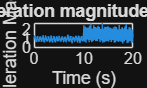


%visuals 

figure;                            % Create new plot window
plot(time, accMag);              % Plot acceleration magnitude and time
title("Acceleration magnitude vs Time"); %title the graph
xlabel("Time (s)");        %title horizontal axis
ylabel("Acceleration Magnitude");  %title vertical axis

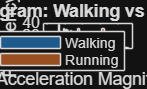


%Histogram

figure;                   %create new plot
histogram(accwalk, 30); hold on;  % walking data histogram
histogram(accrun, 30);            % running data histogram
title("Histogram: Walking vs Running"); %title the graph
xlabel("Acceleration Magnitude");   %title the horizontal axis
ylabel("Frequency");    %label the vertical axis
legend("Walking","Running", "location", "northeast");  %add legend, tope right corner

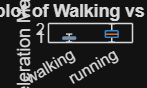


%boxplot

figure;            %create new plot
boxplot([accwalk; accrun], ...   % add Combination of data for boxplot
    [repmat("walking",length(accwalk),1); ...
     repmat("running",length(accrun),1)]);
title("Boxplot of Walking vs Running");  %title the graph
ylabel("Acceleration Magnitude");  %label vertical axis

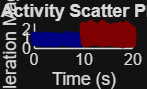


%scatter plot

figure; %create new plot
scatter(time, accMag, 15, double(labels=="running"), "filled"); %scatter plot figure creation 
title("Activity Scatter Plot"); %title the graph
xlabel("Time (s)"); %title horizontal axis
ylabel("Acceleration Magnitude");  %label vertical axis
colormap jet;

## Task 4: Compute simple metrics that differentiate activities

%simple metrics

avgwalk = mean(accwalk);       % Mean magnitude walking (average)
avgrun  = mean(accrun);        % Mean magnitude running (average)

varwalk = var(accwalk);         % Variance walking
varrun  = var(accrun);          % Variance running

[pkw, ~] = findpeaks(accwalk, "MinPeakDistance", 5); % Peaks walking
[pkr, ~] = findpeaks(accrun,  "MinPeakDistance", 5); % Peaks running

peakwalk = length(pkw);        % # of walking peaks
peakrun  = length(pkr);        % # of running peaks

%display numerical results

fprintf("\n            Activity Metrics            \n"); %print title of metric page


            Activity Metrics            



fprintf("\n Walking Metrics: \n");       %display walking metric values


 Walking Metrics: 


fprintf("  Mean:       %.3f\n", avgwalk); %print average walking magnitude

  Mean:       1.002


fprintf("  Variance:   %.3f\n", varwalk); %display walking variance

  Variance:   0.040


fprintf("  Peaks:      %d\n", peakwalk); %display number of walking peaks

  Peaks:      63



fprintf("\nRunning Metrics:\n"); %display running metric values


Running Metrics:


fprintf("  Mean:       %.3f\n", avgrun); %print average running magnitude

  Mean:       1.519


fprintf("  Variance:   %.3f\n", varrun); %display running variance

  Variance:   0.243


fprintf("  Peaks:      %d\n", peakrun); %display number of running peaks

  Peaks:      62




%classify and define system activity
predictrun = accMag > threshold;  % running prediction
truerun = labels == "running";         % Actual running labels

accuracy = sum(predictrun == truerun) / length(time); % Accuracy amount defined

fprintf("\n Threshold-Based Activity Classification: \n");


 Threshold-Based Activity Classification: 


fprintf("  Threshold Used: %.2f\n", threshold);

  Threshold Used: 1.30


fprintf("  Accuracy: %.2f%%\n", accuracy * 100);

  Accuracy: 78.42%



%discussion
fprintf("\n      DISCUSSION          \n");


      DISCUSSION          


fprintf("Walking has lower acceleration, lower variance, and fewer peaks.\n");

Walking has lower acceleration, lower variance, and fewer peaks.


fprintf("Running has higher acceleration, higher variance, and more peaks.\n");

Running has higher acceleration, higher variance, and more peaks.


fprintf("User-controlled thresholding can classify running vs walking.\n");

User-controlled thresholding can classify running vs walking.


fprintf("Sensor data differences allow simple activity recognition.\n");

Sensor data differences allow simple activity recognition.


%{ 
Reflection After Completing the Project: 

- What did you learn?
 Throughout my completion of this project, ... 
 
  - What could be done differently?
many features among this project couldv'e been done differently such as ... 
   
- Rate the project (1 - 10) (1 - represents simple and 10 represents difficult) 
   Rate : ...
%}
